## Get Everything Ready to Go

first clear workspace

clear all
close all
clc

load CompiledPhysio_final.mat

## Reconfiguring Tables to Join

  1.Temp

ID=tempMasterData.Properties.RowNames; %make cell array ID
IDa = cell2table(ID); %turn cell array to table
IDa.Properties.RowNames = ID; %name the rows the original IDs from tempMasterData
tempmasterII=[IDa tempMasterData]; %join IDs (now as table) with data
tempmasterII.Properties.VariableNames{'ID'}='Master_ID';
%rename variable headings
tempmasterII.Properties.VariableNames = {'Master_ID' 'OriginalID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'};
%add data from MasterIDs
dataprestack=join(tempmasterII,masterID);
%remove stuff we might not want
dataprestack = removevars(dataprestack,{'OriginalID' 'Spreadsheet' 'ImportantNotes' 'Var14' 'Var15' 'Var16' 'Var17' 'Var18' 'Var19' 'Var20'})

dataprestack = 261×23 table
           Master_ID    Day01H    Day02H    Day03H    Day04T    Day05T    Day06T    Day07T    Day08T    Day09T    Day10T    Day11T    Day12T      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round
           _________    ______    ______    ______    ______    ______    ______    ______    

2. Weight

weightmasterII=[IDa weightMasterData]; %makes ID the ID table from above
weightmasterII.Properties.VariableNames = {'Master_ID' 'OriginalID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'}

weightmasterII = 261×14 table
           Master_ID       OriginalID       Day01H    Day02H    Day03H    Day04T    Day05T    Day06T    Day07T    Day08T    Day09T    Day10T    Day11T    Day12T
           _________    ________________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    H1      {'H1' }     {'Control_1Inj'}     NaN        NaN      24.1      24.5      24.5      24.4      NaN       NaN       NaN       NaN       NaN      

3. Food

foodmasterII=[IDa deltaFoodData];
foodmasterII.Properties.VariableNames = {'Master_ID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'}

%baselineIDs=table2array(IDa)
[h]=table2array(deltaFoodData(:,["D3Habituation" "D2Habituation" "D1Habituation" "D0Treatment"]))
h_t=transpose(h)
baselineFood_t=nanmean(h_t)
baselineFood=transpose(baselineFood_t)
baselineFoodTable=array2table(baselineFood)
baselineFoodTable.Properties.RowNames=ID

consume_array=table2array(deltaFoodData(:,["D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment" "D5Treatment" "D6Treatment" "D7Treatment" "D8Treatment"]))
intakeI=consume_array-baselineFood
intake=array2table(intakeI)
intake.Properties.RowNames=ID
intake.Properties.VariableNames=["D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment" "D5Treatment" "D6Treatment" "D7Treatment" "D8Treatment"]

foodmasterII=[IDa intake];
foodmasterII.Properties.VariableNames = {'Master_ID' 'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'}

## Stacking Data Tables

%stack day variables from table
prelimstack=stack(dataprestack,{'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'})

prelimstack = 3132×13 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_
             _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    <

weightstack=stack(weightmasterII,{'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'})

weightstack = 3132×4 table
             Master_ID       OriginalID       Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_
             _________    ________________    _______________________________________________________________    _______________________________________________________________

    H1        {'H1'}      {'Control_1Inj'}                                Day01H                                                               NaN                              
    H1_1      {'H1'}      {'Control_1Inj'}                                Day02H                                                               NaN                              
    H1_2      {'H1'}      {'Control_1Inj'}                                Day

foodstack=stack(foodmasterII,{'Day01H' 'Day02H' 'Day03H' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T' 'Day12T'})

foodstack = 3132×3 table
             Master_ID    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1    Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_
             _________    _______________________________________________________________    _______________________________________________________________

    H1        {'H1'}                                  Day01H                                                               NaN                              
    H1_1      {'H1'}                                  Day02H                                                               NaN                              
    H1_2      {'H1'}                                  Day03H                                                               NaN                              
    H1_3      {'H1'

## Reconfiguring Stacks to Join

prelimstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_'}='Temp';
prelimstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1'}='Day';
weightstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_'}='Weight';
foodstack.Properties.VariableNames{'Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_'}='Food';

foodstack.Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1=[]; %get rid of day column 
foodstack.Master_ID=[]; %get rid of MasterID column
weightstack.Day01H_Day02H_Day03H_Day04T_Day05T_Day06T_Day07T_Day08T_Day09_1=[];
weightstack.Master_ID=[];
weightstack.OriginalID=[];

## Joining Stacks

alldataprelim = [prelimstack,foodstack]; %combine with food
alldata = [alldataprelim,weightstack] %combine with weight

alldata = 3132×15 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round     Day      Temp    Food    Weight
             _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______    ____

alldataII=stack(alldata,{'Condition_H_C_'})

alldataII = 3132×16 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round     Day      Temp    Food    Weight    Condition_H_C__Indicator    Condition_H_C_
             _________    ________________    ________    ________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______    

## Making Graphs

1.Temp

a=gramm('x',alldataII.Day,'y',alldataII.Temp,'color',alldataII.Condition_H_C_)

a =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


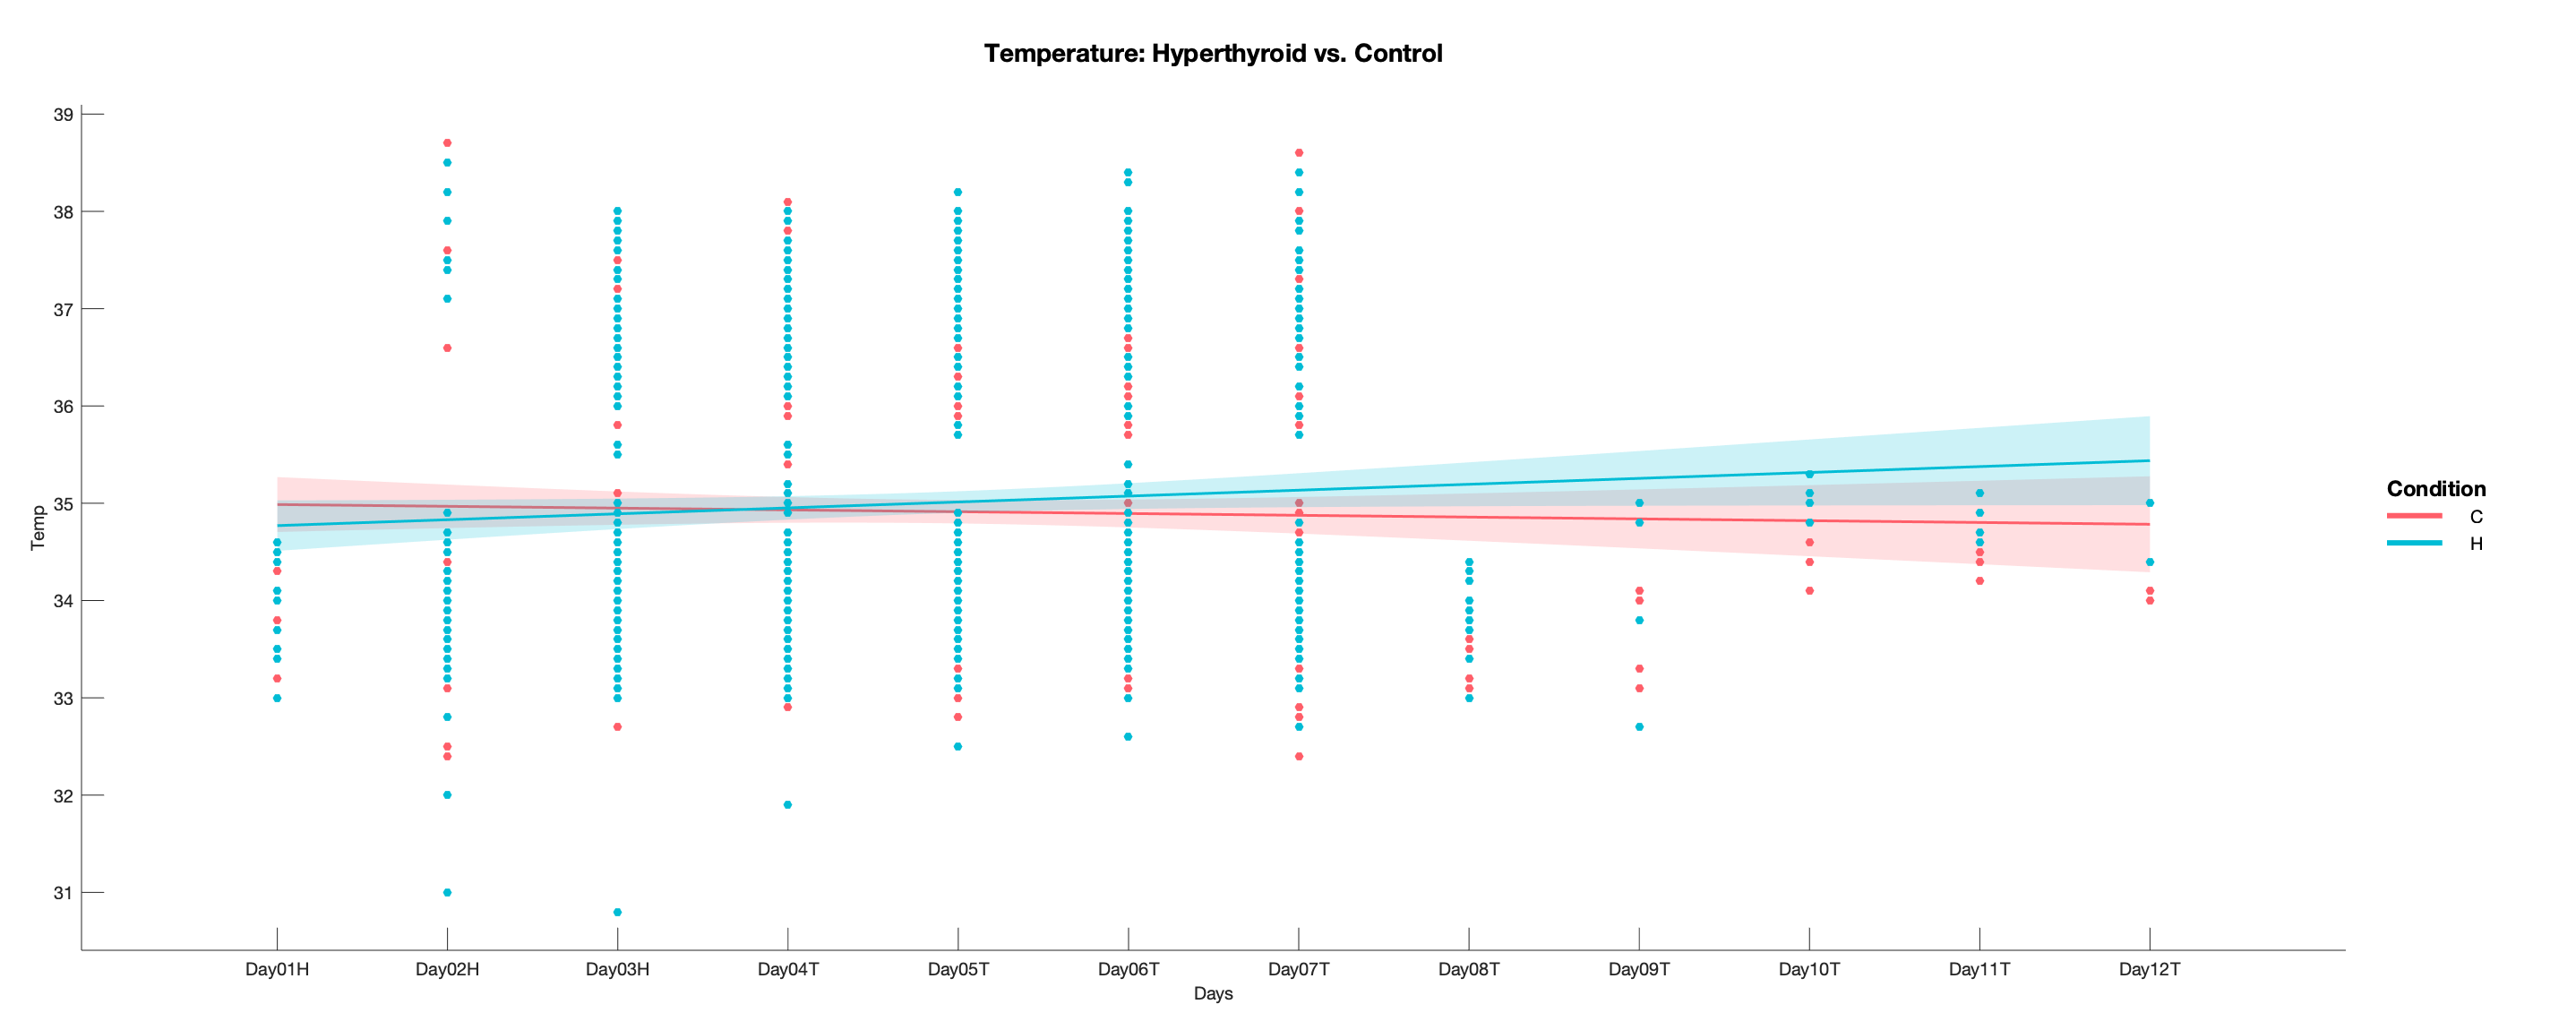

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


a.geom_point();
a.stat_glm();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Temperature: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
a.draw()


dayfilter= alldata.Day ~="Day01H","Day02H","Day07T","Day08T","Day09T","Day10T","Day11T","Day12T"

dayfilter = 3132×1 logical array
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1


ans = "Day02H"

ans = "Day07T"

ans = "Day08T"

ans = "Day09T"

ans = "Day10T"

ans = "Day11T"

ans = "Day12T"

days=alldata(dayfilter,:)

days = 2871×15 table
             Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round     Day      Temp    Food    Weight
             _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______    ____


b=gramm('x',alldata.Day,'y',alldata.Weight,'color',alldata.Condition_H_C_,'subset',alldata.Day~="Day01H" & alldata.Day~="Day02H" & alldata.Day~="Day12T" & alldata.Day~="Day11T" & alldata.Day~="Day10T" & alldata.Day~="Day09T" & alldata.Day~="Day08T")

b =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


b.geom_jitter('width',0.4,'height',0, "dodge",1);
b.stat_violin('fill','transparent','dodge', 1);
b.set_names('x','Days','y','Weight','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


b.set_names("color",'H','x','Days','y','Weight','color','Condition')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


b.set_names("column",'Day1''Day2''Day3''Day4''Day5')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


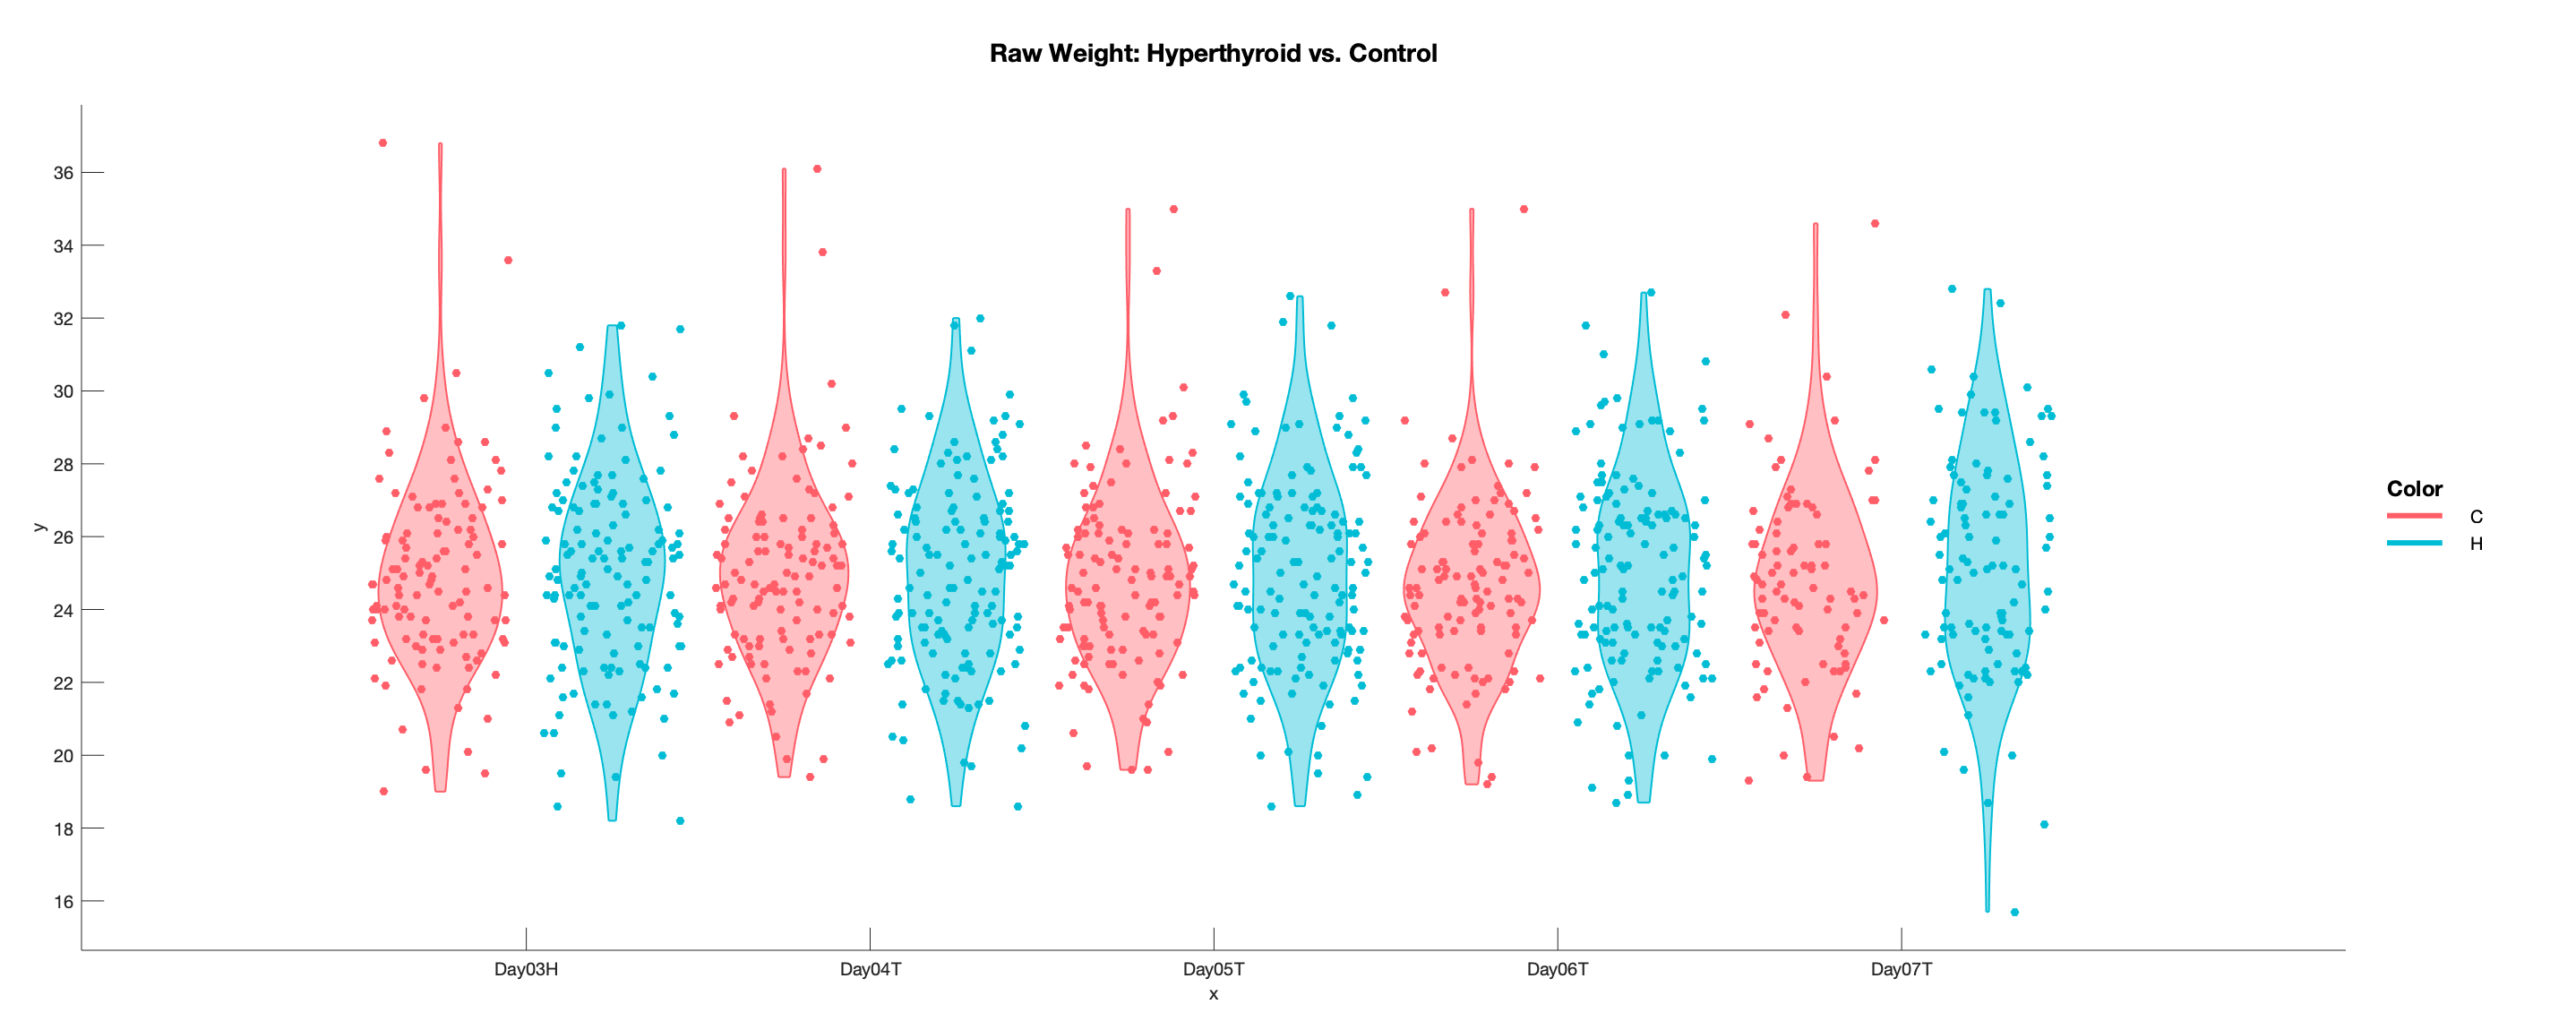

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


b.set_title('Raw Weight: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
b.draw


c=gramm('x',alldata.Day,'y',alldata.Temp,'color',alldata.Condition_H_C_)

Unrecognized table variable name 'Condition'.

2. Food Intake

a=gramm('x',alldataII.Day,'y',alldataII.Food,'color',alldataII.Condition_H_C_)
a.geom_point();
a.stat_glm();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Food Intake: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
a.draw()

3. Weight

a=gramm('x',alldataII.Day,'y',alldataII.Weight,'color',alldataII.Condition_H_C_)
a.geom_point();
a.stat_glm();
a.set_names('x','Days','y','Temp','color','Condition');
a.set_title('Weight: Hyperthyroid vs. Control');
figure('Position',[100 100 2000 800]);
a.draw()

%baselineIDs=table2array(IDa)
%Making detla food delta stack

[h]=table2array(deltaFoodData(:,["D3Habituation" "D2Habituation" "D1Habituation" "D0Treatment"]))

h =        NaN       NaN       NaN    4.3000
       NaN       NaN       NaN    3.9000
       NaN       NaN       NaN    2.7000
       NaN       NaN       NaN    3.6000
       NaN       NaN       NaN    3.9000
       NaN       NaN       NaN    3.6000
       NaN       NaN       NaN    4.8000
       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    4.5000
       NaN       NaN       NaN    4.5000


h_t=transpose(h)

h_t =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    3.9000    5.1000    5.3000    4.7000       NaN       NaN       NaN       NaN    6.4000    3.7000    6.0000    5.6000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    3.0000    4.1000       NaN       NaN    5.3000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   

baselineFood_t=nanmean(h_t)

baselineFood_t =     4.3000    3.9000    2.7000    3.6000    3.9000    3.6000    4.8000       NaN    4.5000    4.5000    4.4333    4.8000    6.1000    6.3667    4.5000    4.5000    4.7000    5.3000    6.1000    4.2333    4.5667    5.3333    4.2000    3.5000    4.4000    4.7000       NaN       NaN    5.4000    4.7000    4.5000    4.2000    3.4333    4.3000    5.2500    4.9500    4.6667    4.2500    4.7500    4.9500    4.2000    4.6000       NaN       NaN       NaN       NaN       NaN       NaN       NaN    3.3000


baselineFood=transpose(baselineFood_t)

baselineFood =     4.3000
    3.9000
    2.7000
    3.6000
    3.9000
    3.6000
    4.8000
       NaN
    4.5000
    4.5000


baselineFoodTable=array2table(baselineFood)

baselineFoodTable = 261×1 table
    baselineFood
    ____________

          4.3   
          3.9   
          2.7   
          3.6   
          3.9   
          3.6   
          4.8   
          NaN   
          4.5   
          4.5   
       4.4333   
          4.8   
          6.1   
       6.3667   
          4.5   
          4.5   


baselineFoodTable.Properties.RowNames=ID

baselineFoodTable = 261×1 table
           baselineFood
           ____________

    H1           4.3   
    H2           3.9   
    H3           2.7   
    H4           3.6   
    H5           3.9   
    H6           3.6   
    H7           4.8   
    H8           NaN   
    H9           4.5   
    H10          4.5   
    H11       4.4333   
    H12          4.8   
    H13          6.1   
    H14       6.3667   
    H15          4.5   
    H16          4.5   



consume_array=table2array(deltaFoodData(:,["D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment" "D5Treatment" "D6Treatment" "D7Treatment" "D8Treatment"]))

consume_array =     4.1000    3.7000       NaN       NaN       NaN       NaN       NaN       NaN
    4.9000    4.4000       NaN       NaN       NaN       NaN       NaN       NaN
    4.3000    5.2000       NaN       NaN       NaN       NaN       NaN       NaN
    4.9000    5.4000       NaN       NaN       NaN       NaN       NaN       NaN
    3.9000    1.4000       NaN       NaN       NaN       NaN       NaN       NaN
    3.9000    4.8000       NaN       NaN       NaN       NaN       NaN       NaN
    5.1000    5.6000       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.2000    3.4000       NaN       NaN       NaN       NaN       NaN       NaN
    5.1000    4.4000       NaN       NaN       NaN       NaN       NaN       NaN


intakeI=consume_array-baselineFood

intakeI =    -0.2000   -0.6000       NaN       NaN       NaN       NaN       NaN       NaN
    1.0000    0.5000       NaN       NaN       NaN       NaN       NaN       NaN
    1.6000    2.5000       NaN       NaN       NaN       NaN       NaN       NaN
    1.3000    1.8000       NaN       NaN       NaN       NaN       NaN       NaN
         0   -2.5000       NaN       NaN       NaN       NaN       NaN       NaN
    0.3000    1.2000       NaN       NaN       NaN       NaN       NaN       NaN
    0.3000    0.8000       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.7000   -1.1000       NaN       NaN       NaN       NaN       NaN       NaN
    0.6000   -0.1000       NaN       NaN       NaN       NaN       NaN       NaN


intake=array2table(intakeI)

intake = 261×8 table
    intakeI1    intakeI2    intakeI3    intakeI4    intakeI5    intakeI6    intakeI7    intakeI8
    ________    ________    ________    ________    ________    ________    ________    ________

       -0.2        -0.6       NaN         NaN         NaN         NaN         NaN         NaN   
          1         0.5       NaN         NaN         NaN         NaN         NaN         NaN   
        1.6         2.5       NaN         NaN         NaN         NaN         NaN         NaN   
        1.3         1.8       NaN         NaN         NaN         NaN         NaN         NaN   
          0        -2.5       NaN         NaN         NaN         NaN         NaN         NaN   
        0.3         1.2    

intake.Properties.RowNames=ID

intake = 261×8 table
           intakeI1    intakeI2    intakeI3    intakeI4    intakeI5    intakeI6    intakeI7    intakeI8
           ________    ________    ________    ________    ________    ________    ________    ________

    H1        -0.2        -0.6       NaN         NaN         NaN         NaN         NaN         NaN   
    H2           1         0.5       NaN         NaN         NaN         NaN         NaN         NaN   
    H3         1.6         2.5       NaN         NaN         NaN         NaN         NaN         NaN   
    H4         1.3         1.8       NaN         NaN         NaN         NaN         NaN         NaN   
    H5

intake.Properties.VariableNames=["D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment" "D5Treatment" "D6Treatment" "D7Treatment" "D8Treatment"]

intake = 261×8 table
           D1Treatment    D2Treatment    D3Treatment    D4Treatment    D5Treatment    D6Treatment    D7Treatment    D8Treatment
           ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

    H1          -0.2           -0.6          NaN            NaN            NaN            NaN            NaN            NaN    
    H2             1            0.5          NaN            NaN            NaN            NaN            NaN            NaN    
    H3           1.6            2.5          NaN            NaN            NaN            NaN            NaN            NaN    
    H4 



intakemasterII=[IDa intake];
intakemasterII.Properties.VariableNames = {'Master_ID' 'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T'}

intakemasterII = 261×9 table
           Master_ID    Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
           _________    _______    _______    ______    ______    ______    ______    ______    ______

    H1      {'H1' }        -0.2       -0.6     NaN       NaN       NaN       NaN       NaN       NaN  
    H2      {'H2' }           1        0.5     NaN       NaN       NaN       NaN       NaN       NaN  
    H3      {'H3' }         1.6        2.5     NaN       NaN       NaN       NaN       NaN       NaN  
    H4      {'H4' }         1.3        1.8     NaN       NaN       NaN       NaN 


intakemasterI=join(masterID,intakemasterII)

intakemasterI = 261×28 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                                      ImportantNotes                        Var14      Var15         Var16         Var17       Var18    Var19      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _

intakemasterI.ImportantNotes=[]

intakemasterI = 261×27 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var15         Var16         Var17       Var18    Var19      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________<

intakemasterI.Var15=[]

intakemasterI = 261×26 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var16         Var17       Var18    Var19      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________

intakemasterI.Var16=[]

intakemasterI = 261×25 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var17       Var18    Var19      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________    _____________

intakemasterI.Var17=[]

intakemasterI = 261×24 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Var18    Var19      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________    ______________    _________

intakemasterI.Var18=[]

intakemasterI = 261×23 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Var19      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________    ______________    _____________________________

intakemasterI.Var19=[]

intakemasterI = 261×22 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var20       Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________    ______________    _____________________________    ___________

intakemasterI.Var20=[]

intakemasterI = 261×21 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________    ______________    _____________________________    ______________    _______

intakemasterI.Var14=[]

intakemasterI = 261×20 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
    _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    

intakemasterI.Properties.RowNames=ID

intakemasterI = 261×20 table
           Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day04T     Day05T     Day06T    Day07T    Day08T    Day09T    Day10T    Day11T
           _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________</


intakestack=stack(intakemasterI,{'Day04T' 'Day05T' 'Day06T' 'Day07T' 'Day08T' 'Day09T' 'Day10T' 'Day11T'})

intakestack = 2088×14 table
            Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_Day10T_Day11T_Indicat    Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_Day10T_Day11T
            _________    ________________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    __

intakestack.Properties.VariableNames{'Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_Day10T_Day11T_Indicat'}='Day';
intakestack.Properties.VariableNames{'Day04T_Day05T_Day06T_Day07T_Day08T_Day09T_Day10T_Day11T'}='deltaIntake';
intakestack.Original_ID=[]

intakestack = 2088×13 table
            Master_ID    Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                   Day      deltaIntake
            _________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______________________________________    ______    _______


b=gramm('x',intakestack.Day,'y',intakestack.deltaIntake,'color',intakestack.Condition_H_C_,'subset',intakestack.Day~="Day11T" & intakestack.Day~="Day10T" & intakestack.Day~="Day09T" & intakestack.Day~="Day08T"')

b =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


b.geom_jitter('width',0.3,'height',0, "dodge",1);
b.stat_violin('width',0.5,'fill','transparent','dodge', 1);
b.set_names('x','Days','y','Change in Food Consumption')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


b.set_title('Change in Food Consumption from Baseline: Control vs. Hyperthyroid');
figure('Position',[100 100 2000 800]);
b.draw

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]



currentFolder='//Users/hannahfarnsworth/Dropbox (HMS)/MTest';
saveFolder='//Users/hannahfarnsworth/Dropbox (HMS)/MTest'

saveFolder = '//Users/hannahfarnsworth/Dropbox (HMS)/MTest'

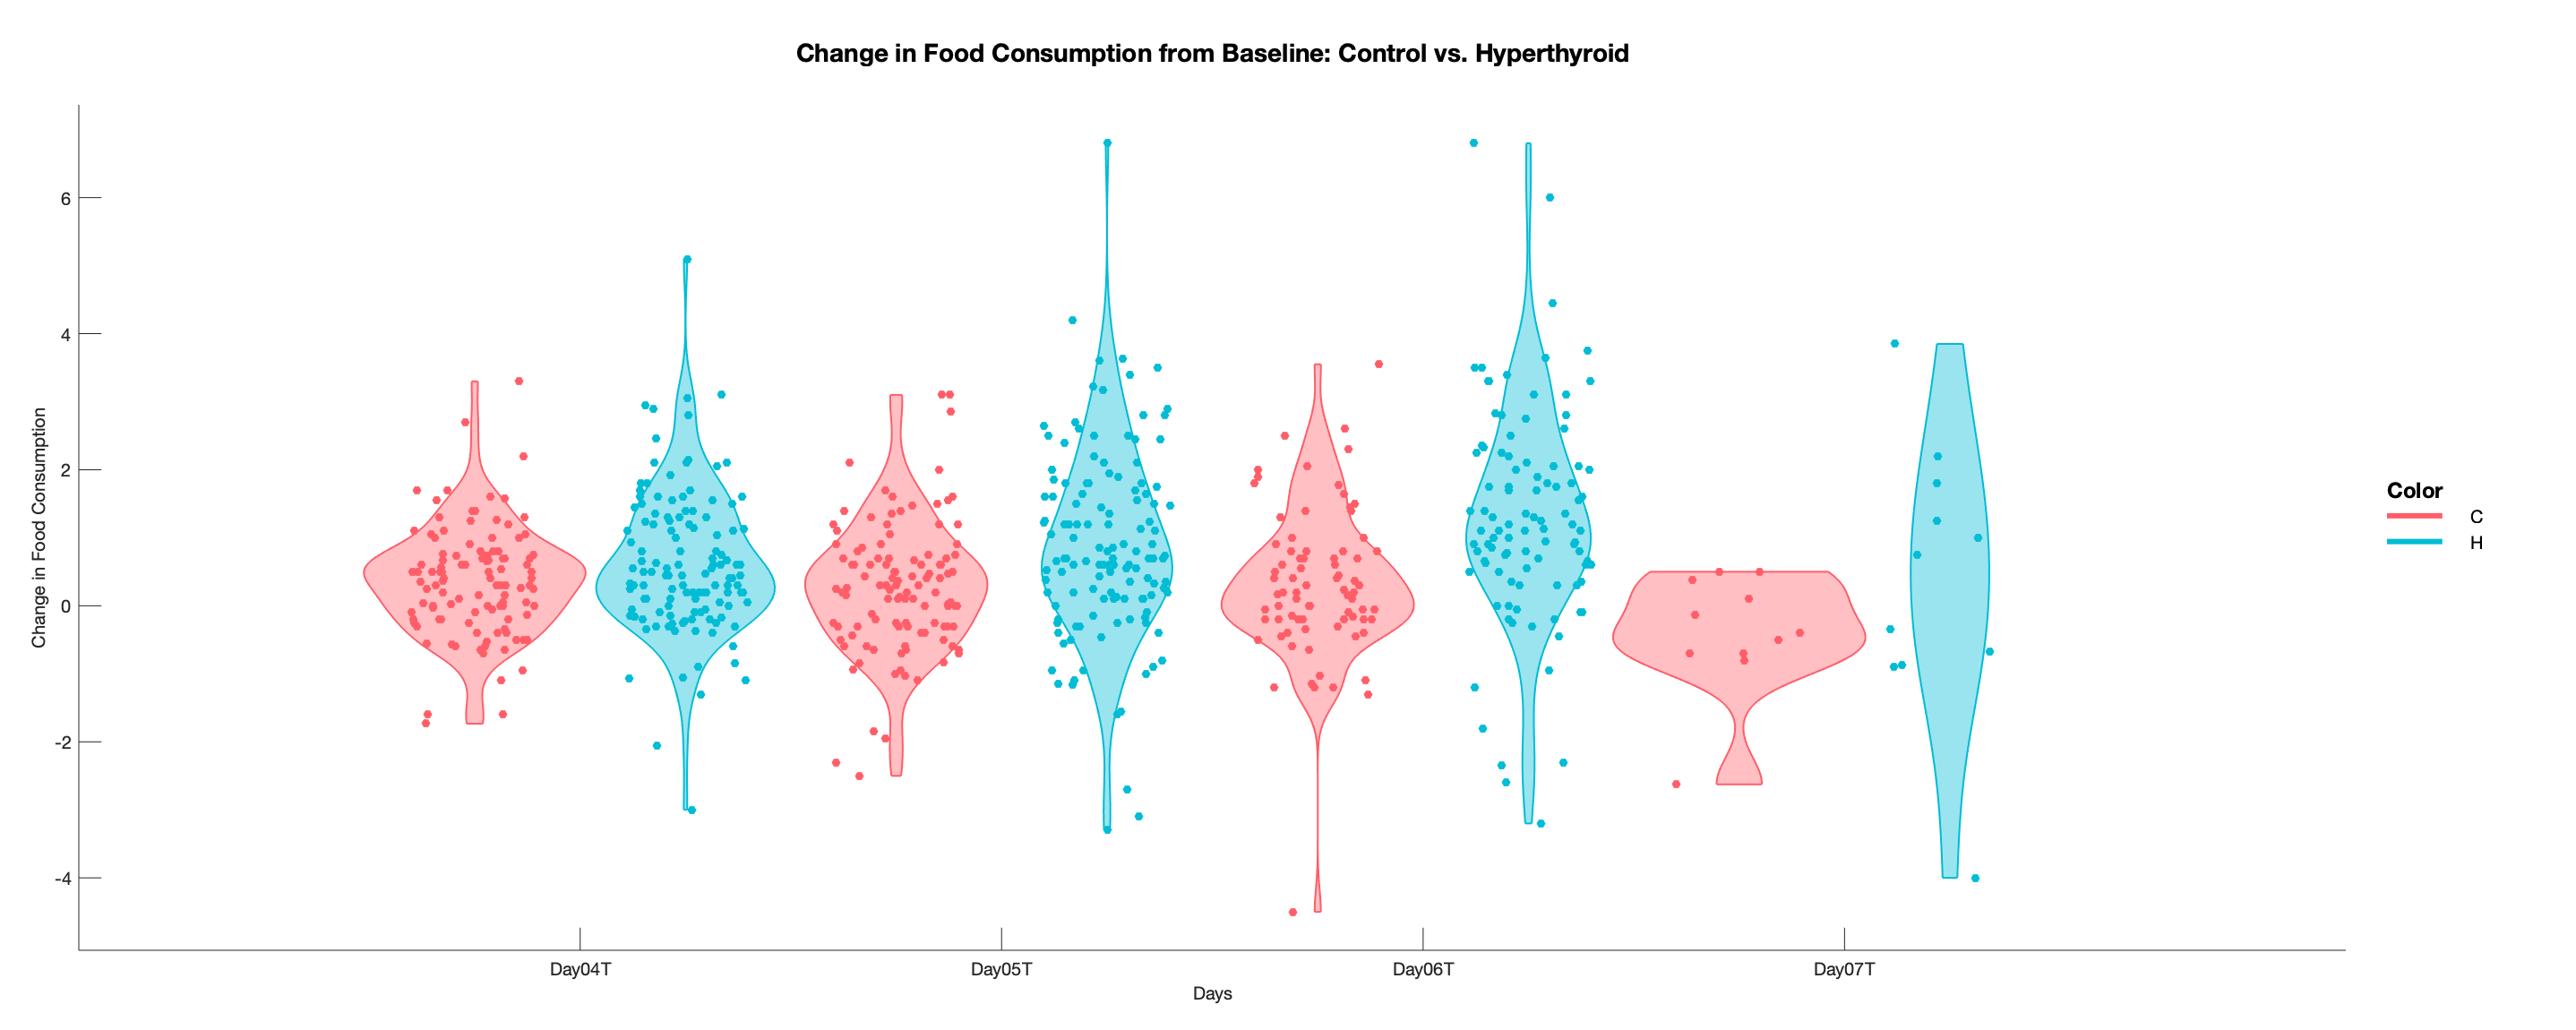

saveas(gcf,'deltafoodvio_jitt.jpg','jpeg')


c=gramm('x',intakestack.Day,'y',intakestack.deltaIntake,'color',intakestack.Condition_H_C_,'subset',intakestack.Day~="Day11T" & intakestack.Day~="Day10T" & intakestack.Day~="Day09T" & intakestack.Day~="Day08T" & intakestack.Day~="Day07T"')

c =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c.stat_boxplot('width',0.5,'dodge', 0.5);
c.set_names('x','Days','y','Change in Food Consumption')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.set_title('Change in Food Consumption from Baseline: Control vs. Hyperthyroid');
figure('Position',[100 100 2000 800]);
c.draw

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


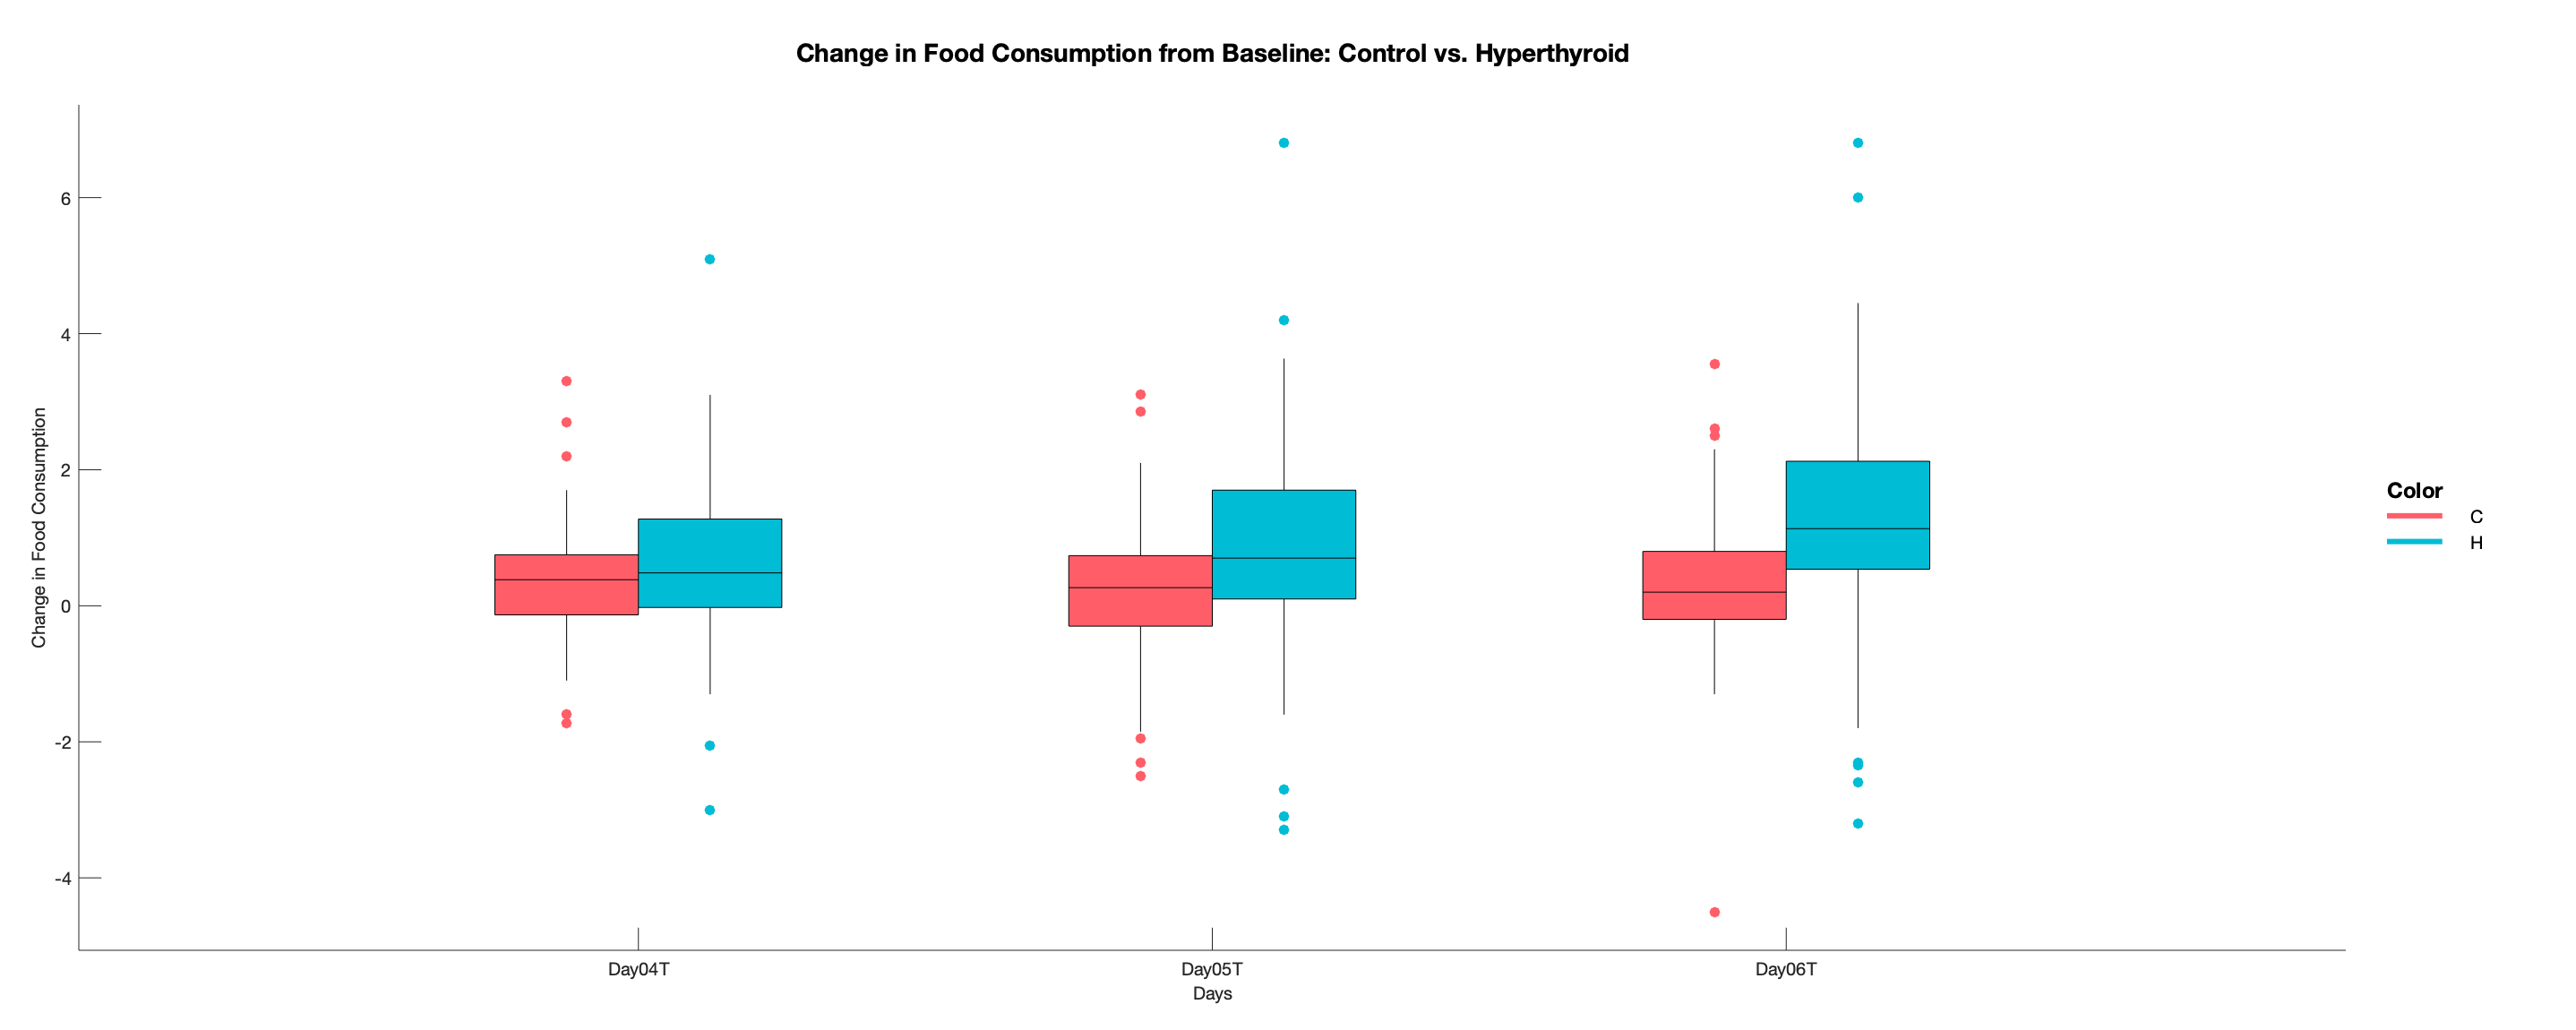


saveas(gcf,'deltafoodbox_3.jpg','jpeg')


d=gramm('x',intakestack.Day,'y',intakestack.deltaIntake,'color',intakestack.Condition_H_C_,'subset',intakestack.Day~="Day11T" & intakestack.Day~="Day10T" & intakestack.Day~="Day09T" & intakestack.Day~="Day08T"')

d =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


d.stat_boxplot('width',0.5,'dodge', 0.5);
d.set_names('x','Days','y','Change in Food Consumption')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


d.set_title('Change in Food Consumption from Baseline: Control vs. Hyperthyroid');
figure('Position',[100 100 2000 800]);
d.draw

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


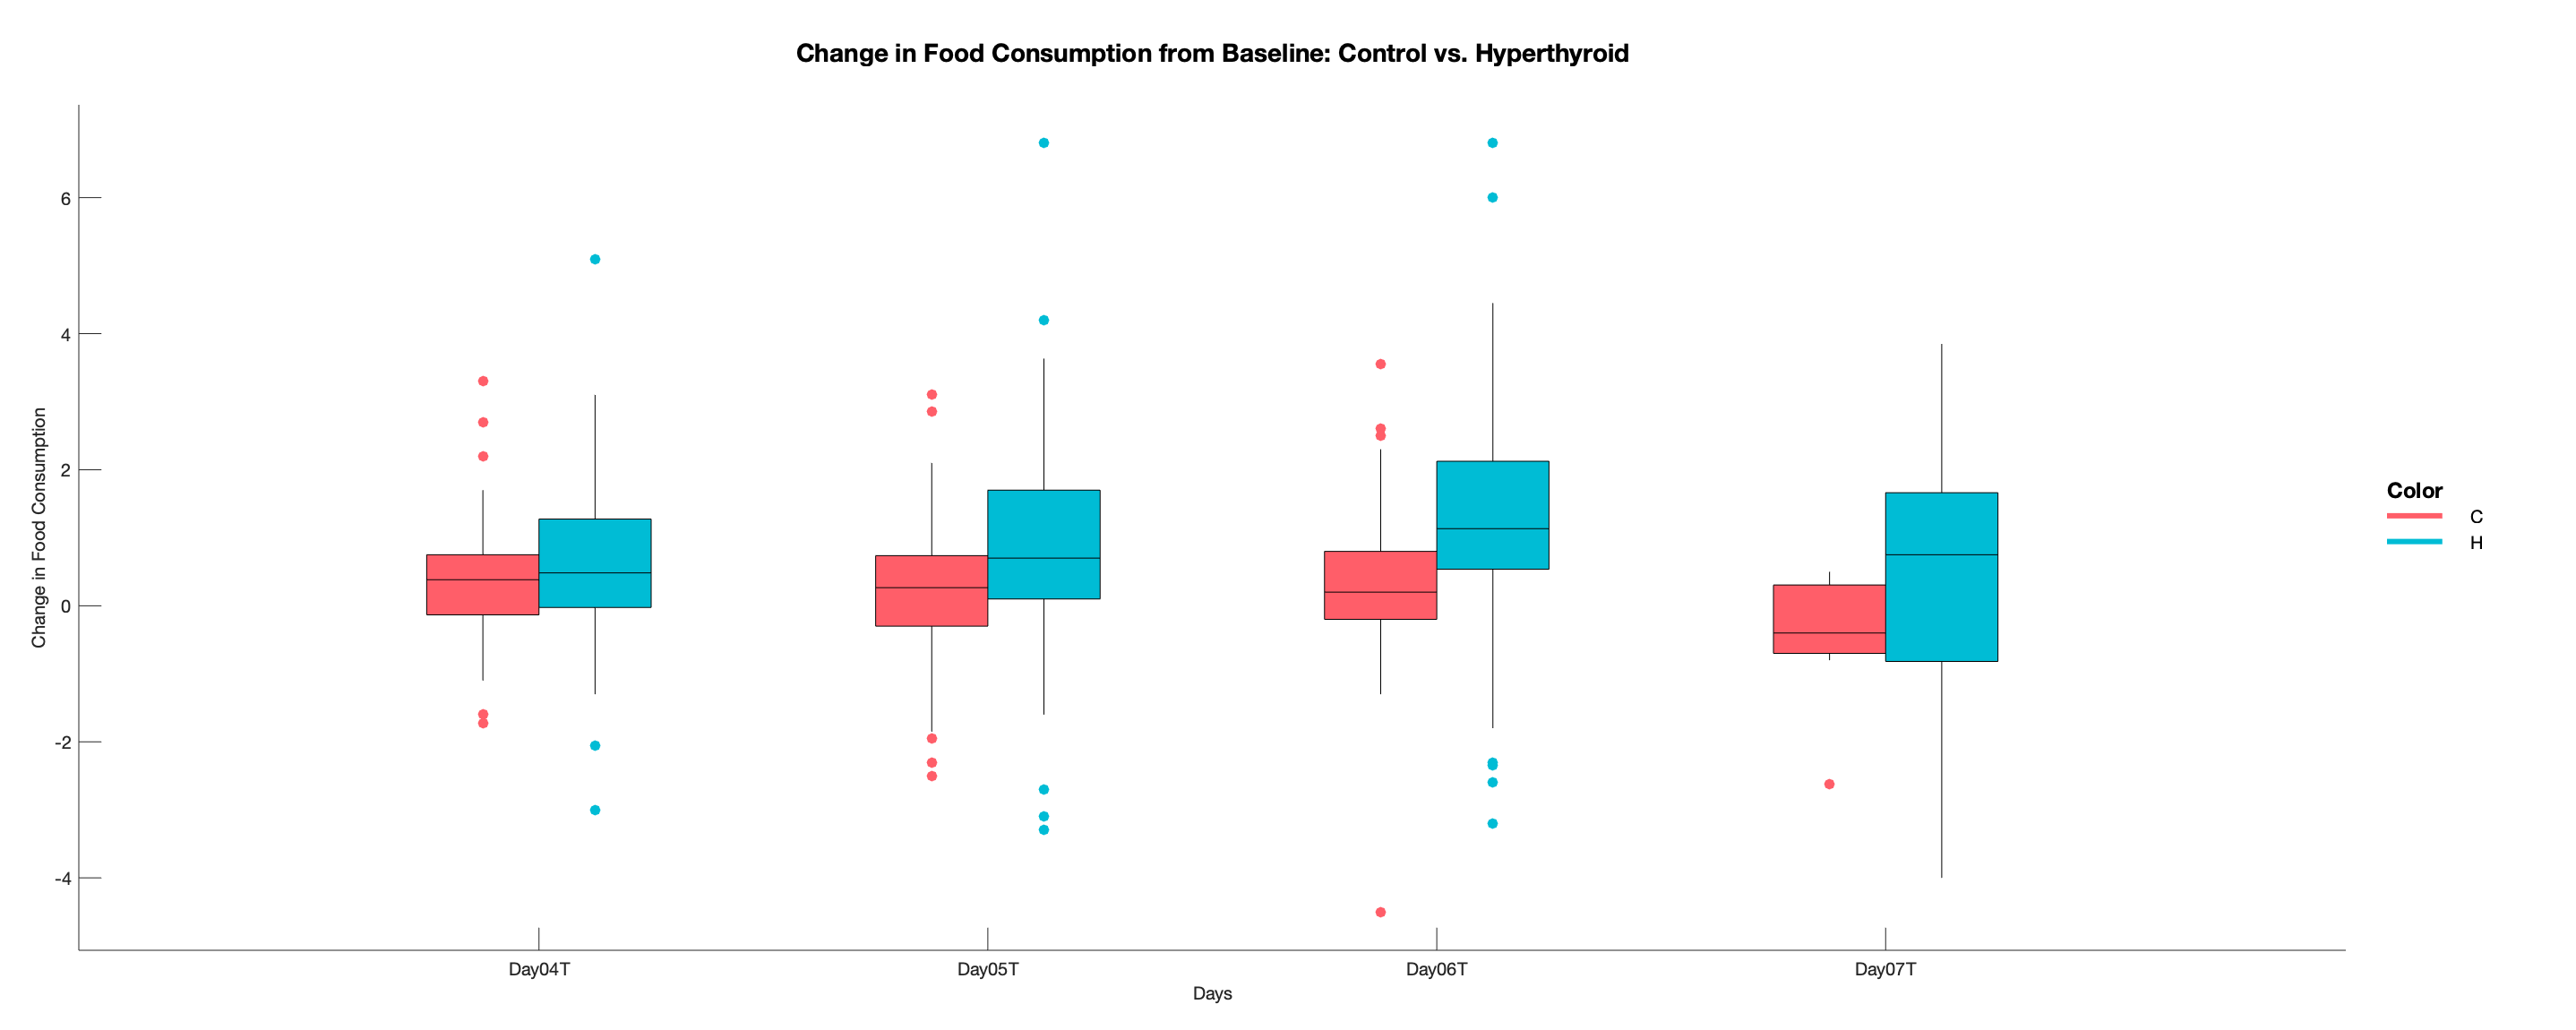


saveas(gcf,'deltafoodbox_4days.jpg','jpeg')

%Get food intake as a fold delta value
[h]=table2array(deltaFoodData(:,["D3Habituation" "D2Habituation" "D1Habituation" "D0Treatment"]))

h =        NaN       NaN       NaN    4.3000
       NaN       NaN       NaN    3.9000
       NaN       NaN       NaN    2.7000
       NaN       NaN       NaN    3.6000
       NaN       NaN       NaN    3.9000
       NaN       NaN       NaN    3.6000
       NaN       NaN       NaN    4.8000
       NaN       NaN       NaN       NaN
       NaN       NaN       NaN    4.5000
       NaN       NaN       NaN    4.5000


h_t=transpose(h);
baselineFood_t=nanmean(h_t)

baselineFood_t =     4.3000    3.9000    2.7000    3.6000    3.9000    3.6000    4.8000       NaN    4.5000    4.5000    4.4333    4.8000    6.1000    6.3667    4.5000    4.5000    4.7000    5.3000    6.1000    4.2333    4.5667    5.3333    4.2000    3.5000    4.4000    4.7000       NaN       NaN    5.4000    4.7000    4.5000    4.2000    3.4333    4.3000    5.2500    4.9500    4.6667    4.2500    4.7500    4.9500    4.2000    4.6000       NaN       NaN       NaN       NaN       NaN       NaN       NaN    3.3000


baselineFood=transpose(baselineFood_t);
baselineFoodTable=array2table(baselineFood);
baselineFoodTable.Properties.RowNames=ID

baselineFoodTable = 261×1 table
           baselineFood
           ____________

    H1           4.3   
    H2           3.9   
    H3           2.7   
    H4           3.6   
    H5           3.9   
    H6           3.6   
    H7           4.8   
    H8           NaN   
    H9           4.5   
    H10          4.5   
    H11       4.4333   
    H12          4.8   
    H13          6.1   
    H14       6.3667   
    H15          4.5   
    H16          4.5   



consume_array=table2array(deltaFoodData(:,["D1Habituation" "D0Treatment" "D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment" "D5Treatment" "D6Treatment" "D7Treatment" "D8Treatment"]));
[foldintakeI]=consume_array./baselineFood;
foldintake=array2table(foldintakeI);
foldintake.Properties.RowNames=ID

foldintake = 261×10 table
           foldintakeI1    foldintakeI2    foldintakeI3    foldintakeI4    foldintakeI5    foldintakeI6    foldintakeI7    foldintakeI8    foldintakeI9    foldintakeI10
           ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    _____________

    H1           NaN               1         0.95349         0.86047           NaN             NaN             NaN             NaN             NaN              NaN     
    H2           NaN               1          1.2564          1.1282           NaN          

foldintake.Properties.VariableNames=["D1Habituation" "D0Treatment" "D1Treatment" "D2Treatment" "D3Treatment" "D4Treatment" "D5Treatment" "D6Treatment" "D7Treatment" "D8Treatment"]

foldintake = 261×10 table
           D1Habituation    D0Treatment    D1Treatment    D2Treatment    D3Treatment    D4Treatment    D5Treatment    D6Treatment    D7Treatment    D8Treatment
           _____________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

    H1            NaN               1        0.95349        0.86047          NaN            NaN            NaN            NaN            NaN            NaN    
    H2            NaN               1         1.2564         1.1282          NaN            NaN            NaN         


foldintakemasterII=[IDa foldintake];
foldintakemasterII.Properties.VariableNames =[{'Master_ID' '-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'}]

foldintakemasterII = 261×11 table
           Master_ID      -1          0          1          2        3      4      5      6      7      8 
           _________    _______    _______    _______    _______    ___    ___    ___    ___    ___    ___

    H1      {'H1' }         NaN          1    0.95349    0.86047    NaN    NaN    NaN    NaN    NaN    NaN
    H2      {'H2' }         NaN          1     1.2564     1.1282    NaN    NaN    NaN    NaN    NaN    NaN
    H3      {'H3' }         NaN          1     1.5926     1.9259    NaN    NaN    NaN    NaN    NaN    NaN
    <


foldintakemasterII=join(masterID,foldintakemasterII);
foldintakemasterII.ImportantNotes=[]

foldintakemasterII = 261×29 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var15         Var16         Var17       Var18    Var19      Var20         -1          0          1          2        3      4      5      6      7      8 
    _________    ___

foldintakemasterII.Var15=[]

foldintakemasterII = 261×28 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var16         Var17       Var18    Var19      Var20         -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    

foldintakemasterII.Var16=[]

foldintakemasterII = 261×27 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var17       Var18    Var19      Var20         -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    ________    

foldintakemasterII.Var17=[]

foldintakemasterII = 261×26 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Var18    Var19      Var20         -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    ________    ________    _

foldintakemasterII.Var18=[]

foldintakemasterII = 261×25 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14    Var19      Var20         -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    ________    ________    ______________    

foldintakemasterII.Var19=[]

foldintakemasterII = 261×24 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      Var20         -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    ________    ________    ______________    __________________

foldintakemasterII.Var20=[]

foldintakemasterII = 261×23 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Var14      -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    ________    ________    ______________    _____________________________    

foldintakemasterII.Var14=[]

foldintakemasterII = 261×22 table
    Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                    -1          0          1          2        3      4      5      6      7      8 
    _________    ________________    ________    ________    ______________    _____________________________    ______________  


foldintakemasterII.Properties.RowNames=ID

foldintakemasterII = 261×22 table
           Master_ID      Original_ID       Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                    -1          0          1          2        3      4      5      6      7      8 
           _________    ________________    ________    ________    ______________    _____________________________    ___________

foldintakestack=stack(foldintakemasterII,{'-1' '0' '1' '2' '3' '4' '5' '6' '7' '8'});
foldintakestack.Properties.VariableNames{'-1_0_1_2_3_4_5_6_7_8_Indicator'}='Day';
foldintakestack.Properties.VariableNames{'-1_0_1_2_3_4_5_6_7_8'}='FoldDeltaIntake';
foldintakestack.Original_ID=[]

foldintakestack = 2610×13 table
            Master_ID    Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day    FoldDeltaIntake
            _________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______________________________________    ___    _____

%Fold RawData deltaIntake Graphing-Jitter

b=gramm('x',foldintakestack.Day,'y',foldintakestack.FoldDeltaIntake,'color',foldintakestack.Condition_H_C_,'subset',foldintakestack.Day~="8" & foldintakestack.Day~="7" & foldintakestack.Day~="6" & foldintakestack.Day~="5" & foldintakestack.Day~="4"')

b =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


b.geom_jitter('dodge',0.4');
b.axe_property('YScale','log')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


b.set_names('x','Days','y','Fold Change in Food Consumption')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


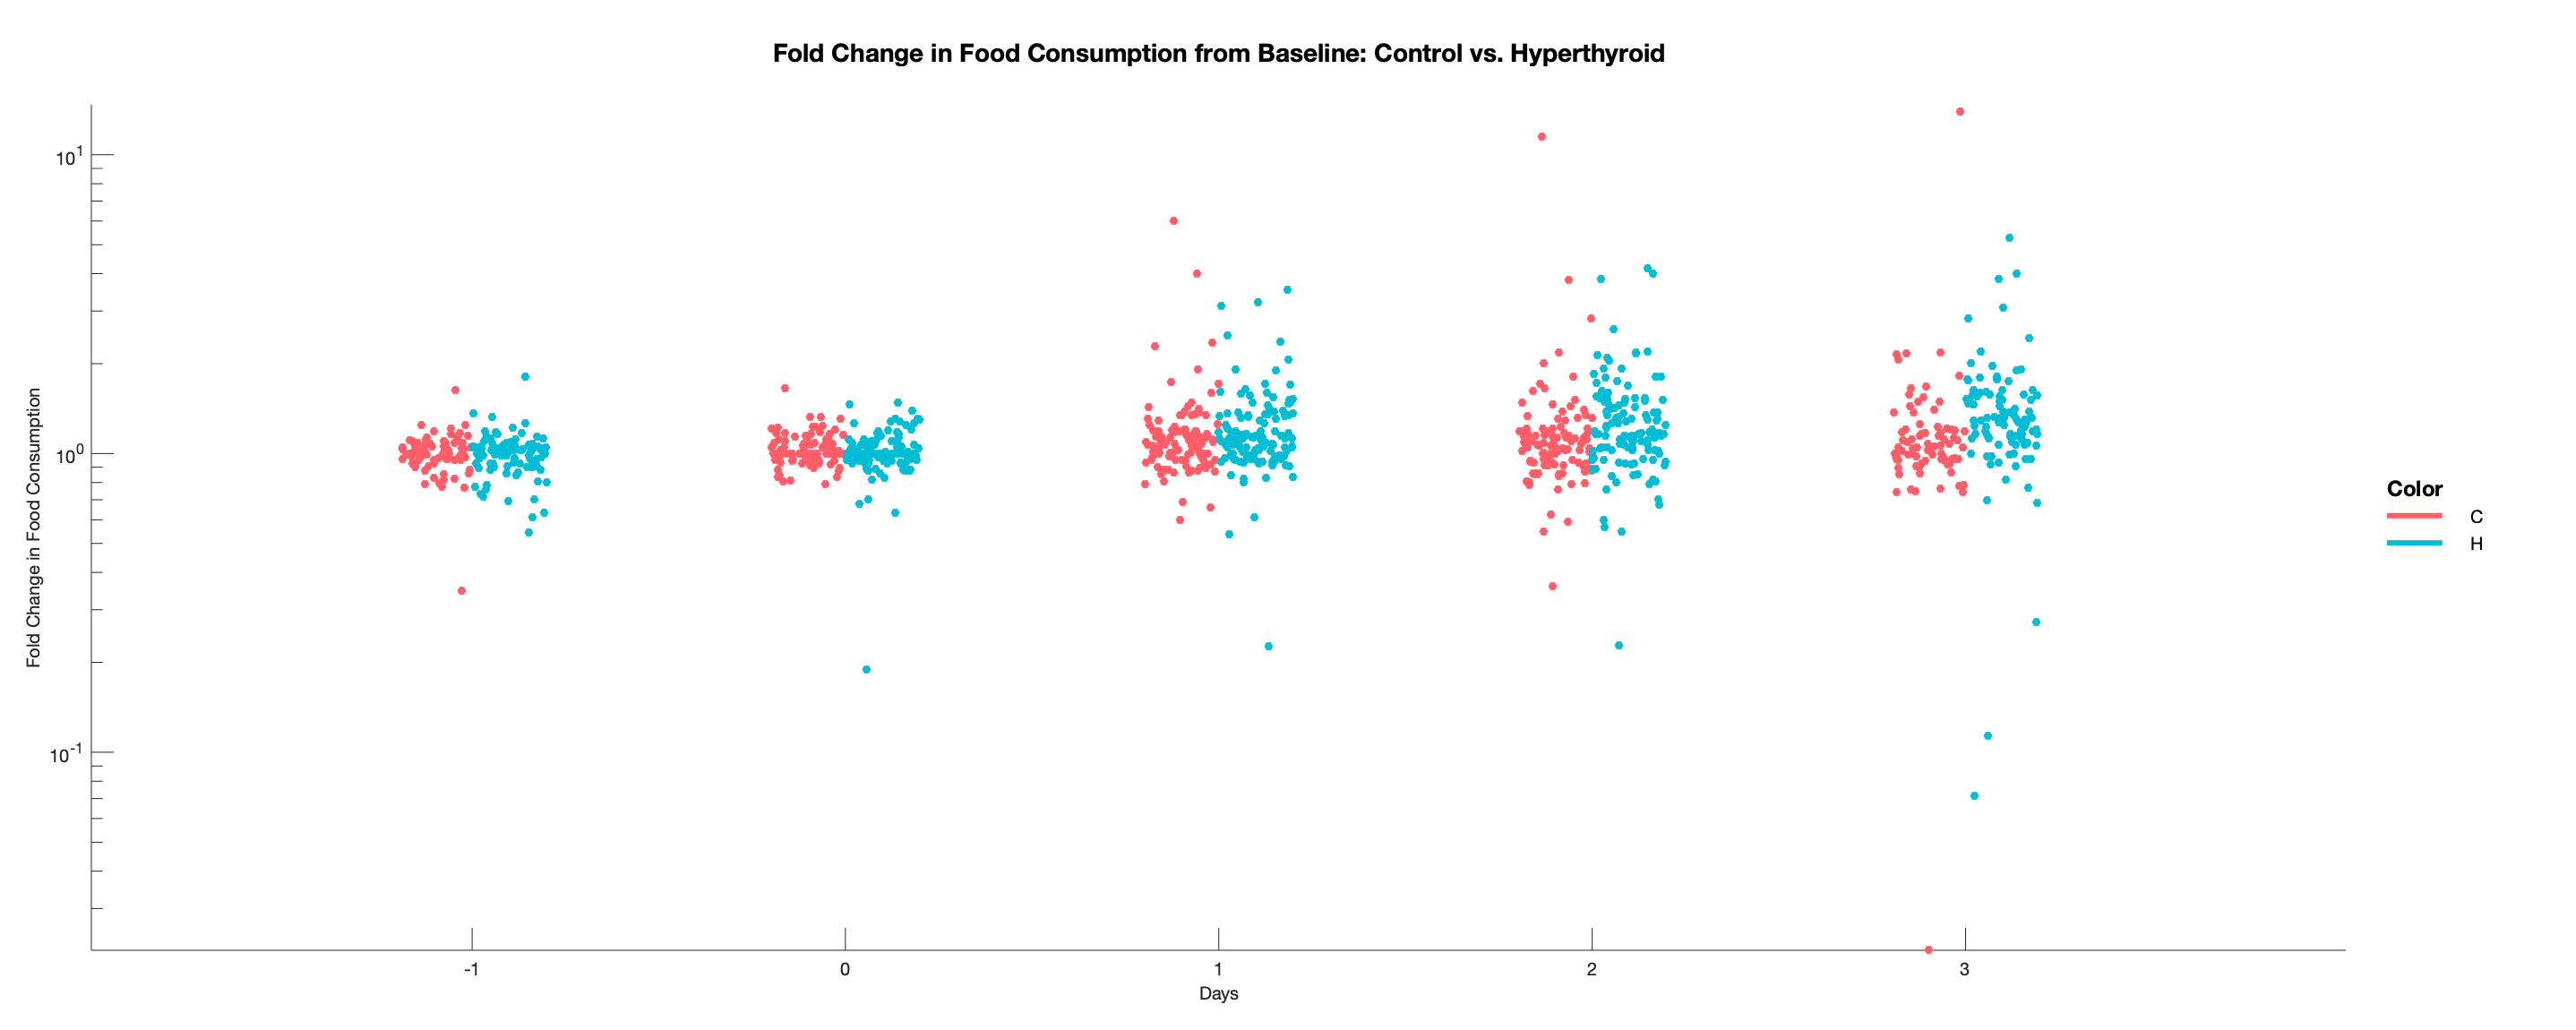

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


b.set_title('Fold Change in Food Consumption from Baseline: Control vs. Hyperthyroid');
figure('Position',[100 100 2000 800]);
b.draw

%Fold RawData deltaIntake Graphing-BoxPlot
d=gramm('x',foldintakestack.Day,'y',foldintakestack.FoldDeltaIntake,'color',foldintakestack.Condition_H_C_,'subset',foldintakestack.Day~="8" & foldintakestack.Day~="7" & foldintakestack.Day~="6" & foldintakestack.Day~="5" & foldintakestack.Day~="4"')

d =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


d.stat_boxplot('width',0.5,'dodge',0.5);
d.axe_property('YScale','log')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


d.set_names('x','Days','y','Fold Change in Food Consumption')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


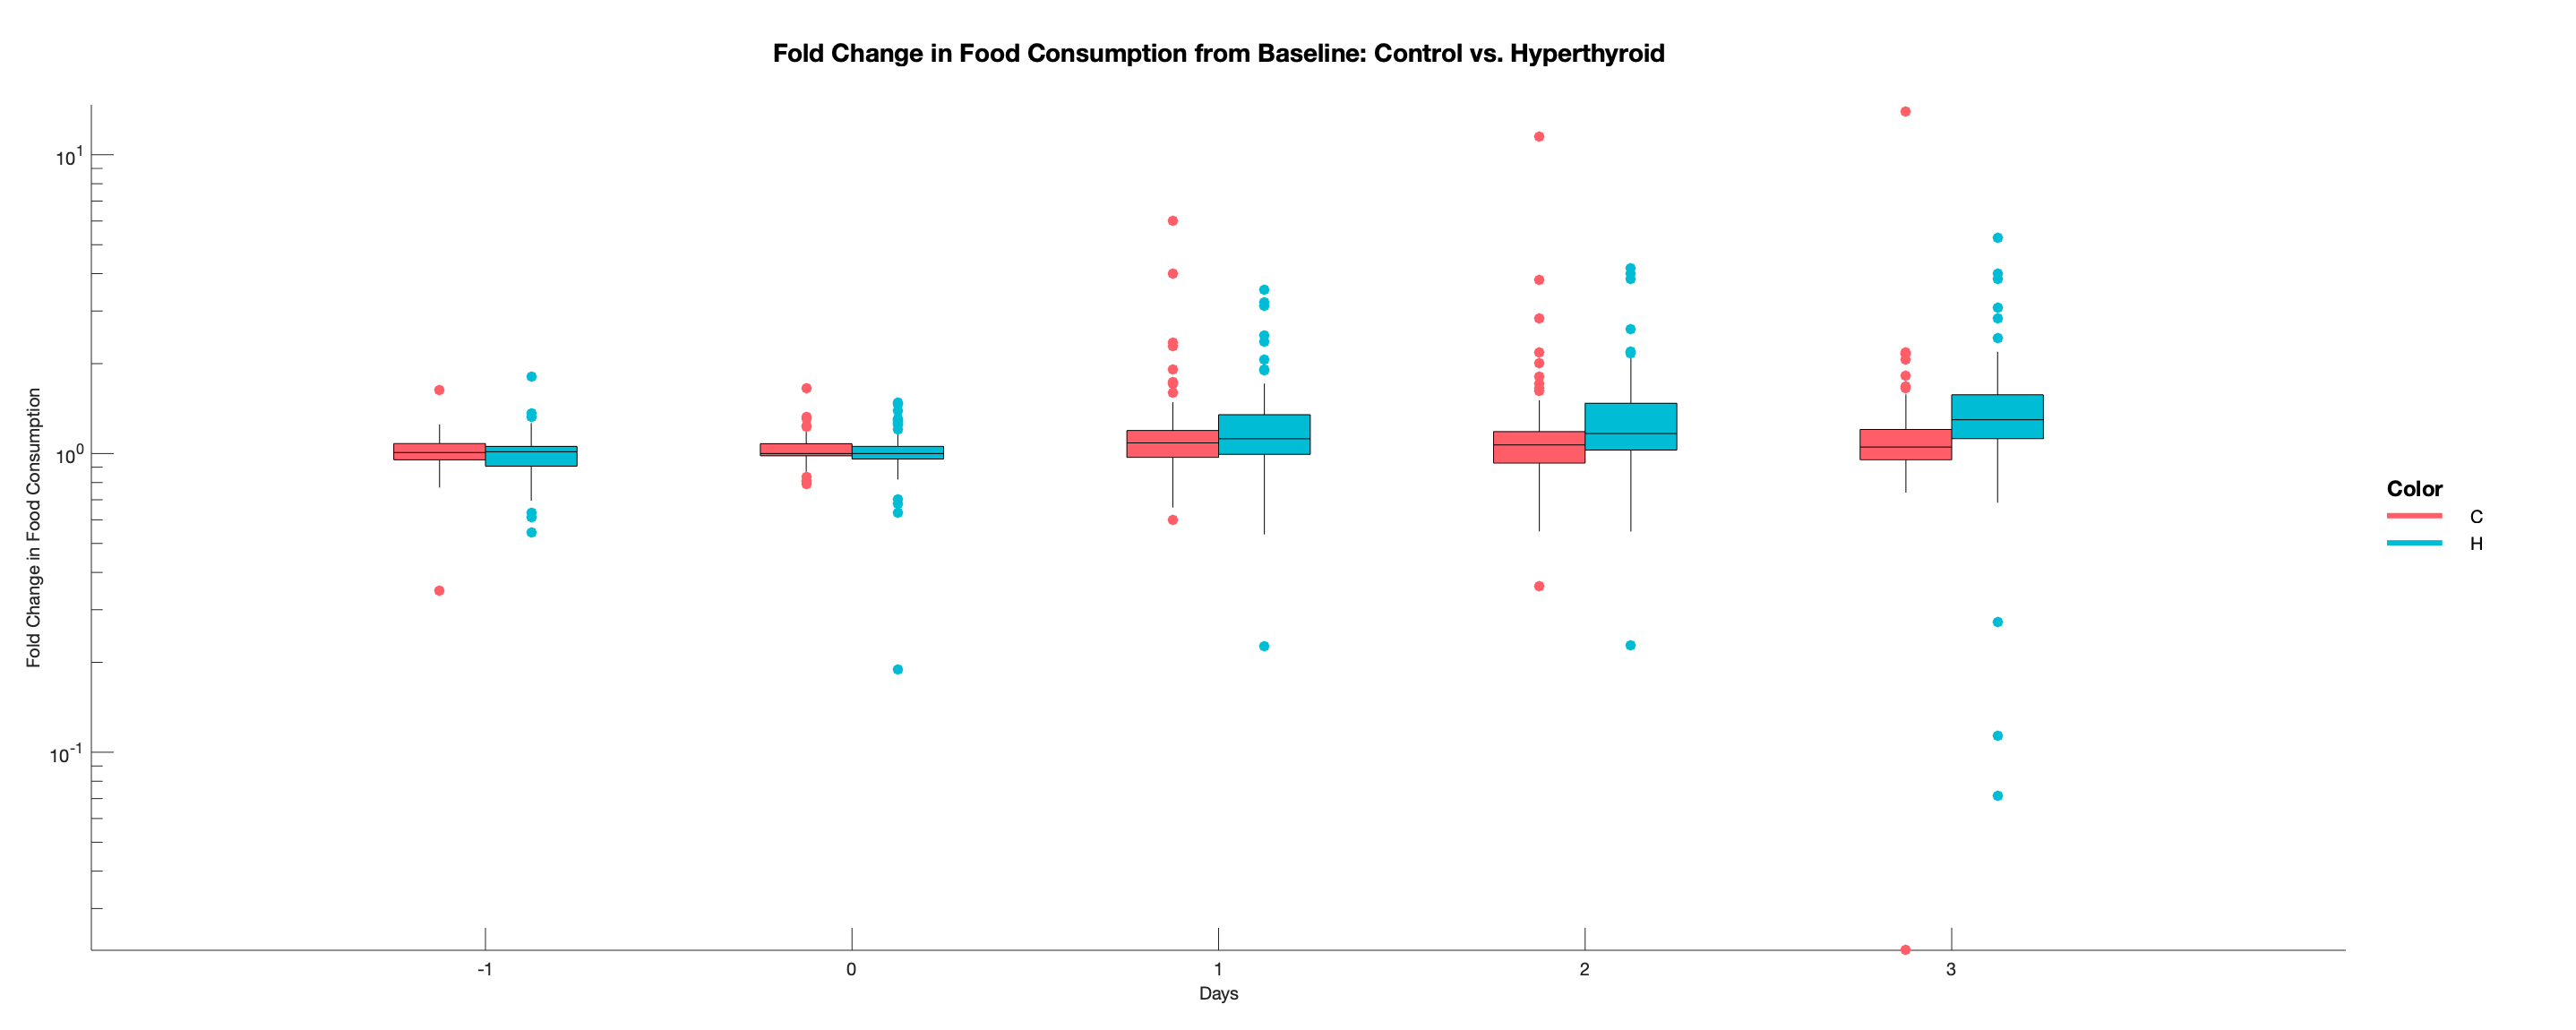

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


d.set_title('Fold Change in Food Consumption from Baseline: Control vs. Hyperthyroid');
figure('Position',[100 100 2000 800]);
d.draw

%Fold deltaIntake with Data in Log10 FOrmal
LogDeltaIntake=log10(foldintakestack.FoldDeltaIntake)

LogDeltaIntake =        NaN
         0
   -0.0207
   -0.0653
       NaN
       NaN
       NaN
       NaN
       NaN
       NaN


LogDelta=array2table(LogDeltaIntake)

LogDelta = 2610×1 table
    LogDeltaIntake
    ______________

            NaN   
              0   
      -0.020685   
      -0.065267   
            NaN   
            NaN   
            NaN   
            NaN   
            NaN   
            NaN   
            NaN   
              0   
       0.099131   
       0.052388   
            NaN   
            NaN   


foldintakestack=[foldintakestack,LogDelta]

foldintakestack = 2610×14 table
            Master_ID    Genotype    Sex_M_F_    Condition_H_C_    AgeAtExp_InjectionStart_days_    ExpDate_start_    Habituation_days_    Treatment_days_                 OriginalExp                 Round                 Spreadsheet                  Day    FoldDeltaIntake    LogDeltaIntake
            _________    ________    ________    ______________    _____________________________    ______________    _________________    _______________    _____________________________________    _____    ______________________________________    <s


c=gramm('x',foldintakestack.Day,'y',foldintakestack.LogDeltaIntake,'color',foldintakestack.Condition_H_C_,'subset',foldintakestack.Day~="8" & foldintakestack.Day~="7" & foldintakestack.Day~="6" & foldintakestack.Day~="5" & foldintakestack.Day~="4"')

c =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


c.geom_jitter('dodge',0.4);
c.stat_summary("interp",'log')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


c.set_names('x','Days','y','Fold Change in Food Consumption')

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


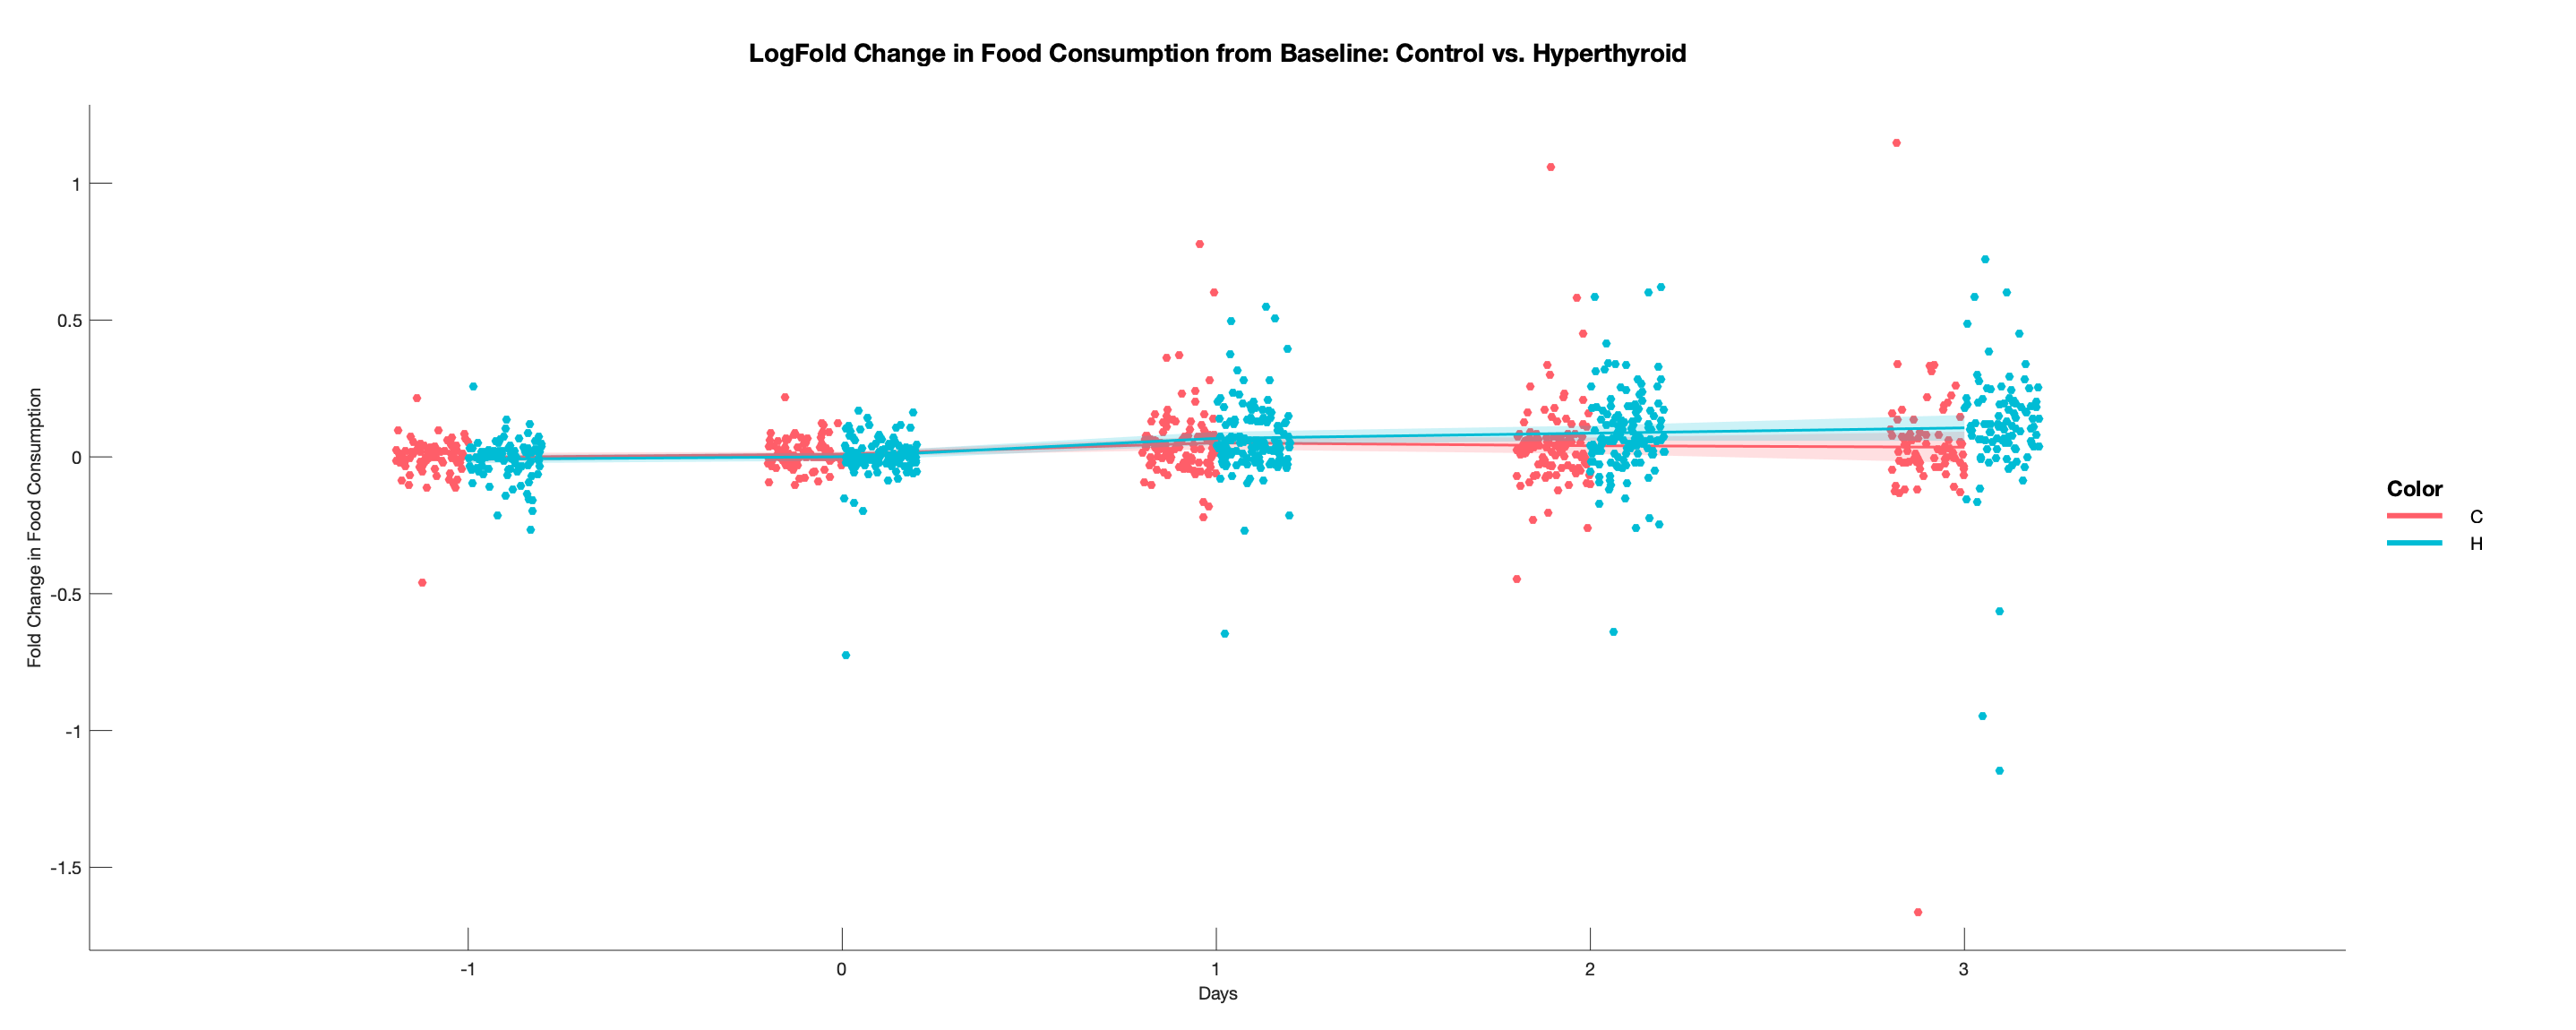

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


c.set_title('LogFold Change in Food Consumption from Baseline: Control vs. Hyperthyroid');
figure('Position',[100 100 2000 800]);
c.draw